close all
clear
clc
sympref('HeavisideAtOrigin',1); % initial setting

### Defining the LTI System

% the matrices of the state equations
A = sym([0  -1  1;...
      1  -2  1;...
      0   1 -1]);
B=sym([1  0;...
      1  1;...
      1  2]);
C = sym([1  0  1;...
      0  1  2 ]);
D = sym([0  0;...
      0  0]);

X0=[1;1;1];

[eigVects, lambdaSET, p] = eig(A); 
% extracting the main diagonal from the square matrix lambdaSET, creating
% a column vector and assigning the col. vector to lambdaSET
lambdaSET = diag(lambdaSET) %autovalori

$$lambdaSET = \left(\begin{array}{c} 0\\ -2\\ -1 \end{array}\right)$$

How many distinct eigenvalues?

lambdaU = unique(lambdaSET);
numel(lambdaU)

ans = 3

#### Evaluating the Algebraic Multiplicity of the Distinct Eigenvalues

What about the algebraic multiplicity?

algMult = zeros(numel(lambdaU),1); % preallocate an array
for j=1:numel(lambdaU)
    algMult(j) = sum(double(lambdaSET)==double(lambdaU(j)));
end % for j
disp(lambdaU)

$$\left(\begin{array}{c} -2\\ -1\\ 0 \end{array}\right)$$

disp(algMult)

     1
     1
     1



#### Evaluating the Geometric Multiplicity of the Distinct Eigenvalues

What about the geometric multiplicity? 

disp(eigVects)

$$\left(\begin{array}{ccc} 1 & -1 & -1\\ 1 & -1 & 0\\ 1 & 1 & 1 \end{array}\right)$$

disp(lambdaSET)

$$\left(\begin{array}{c} 0\\ -2\\ -1 \end{array}\right)$$

disp(p)

     1     2     3



syms z n 
zIA = z*eye(size(A))-A;
zIA_inv = inv(zIA);

A_1 = limit(z*zIA_inv,z, lambdaSET(1) ) 

$$A\_1 = \left(\begin{array}{ccc} \frac{1}{2} & 0 & \frac{1}{2}\\ \frac{1}{2} & 0 & \frac{1}{2}\\ \frac{1}{2} & 0 & \frac{1}{2} \end{array}\right)$$

A_2 = limit((z-lambdaSET(2))*zIA_inv,z, lambdaSET(2) ) 

$$A\_2 = \left(\begin{array}{ccc} -\frac{1}{2} & 1 & -\frac{1}{2}\\ -\frac{1}{2} & 1 & -\frac{1}{2}\\ \frac{1}{2} & -1 & \frac{1}{2} \end{array}\right)$$

A_3 = limit((z-lambdaSET(3))*zIA_inv,z, lambdaSET(3) ) 

$$A\_3 = \left(\begin{array}{ccc} 1 & -1 & 0\\ 0 & 0 & 0\\ -1 & 1 & 0 \end{array}\right)$$

Ak = simplify(A_1*kroneckerDelta(n) +A_2*(lambdaSET(2)^n) +A_3*(lambdaSET(3)^n)  )

$$Ak = \begin{array}{l} \left(\begin{array}{ccc} {\left(-1\right)}^{n}-\frac{{\left(-2\right)}^{n}}{2}+\frac{\delta_{n,0}}{2} & {\left(-2\right)}^{n}-{\left(-1\right)}^{n} & \sigma_{1}\\ \sigma_{1} & {\left(-2\right)}^{n} & \sigma_{1}\\ \frac{{\left(-2\right)}^{n}}{2}-{\left(-1\right)}^{n}+\frac{\delta_{n,0}}{2} & {\left(-1\right)}^{n}-{\left(-2\right)}^{n} & \frac{{\left(-2\right)}^{n}}{2}+\frac{\delta_{n,0}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\delta_{n,0}}{2}-\frac{{\left(-2\right)}^{n}}{2} \end{array}$$

zIA_3 = z*eye(size(A))-A;
zIA3_inv = inv(zIA_3);
Ak1 = simplify(iztrans(z*zIA3_inv))

$$Ak1 = \begin{array}{l} \left(\begin{array}{ccc} {\left(-1\right)}^{n}-\frac{{\left(-2\right)}^{n}}{2}+\frac{\delta_{n,0}}{2} & {\left(-2\right)}^{n}-{\left(-1\right)}^{n} & \sigma_{1}\\ \sigma_{1} & {\left(-2\right)}^{n} & \sigma_{1}\\ \frac{{\left(-2\right)}^{n}}{2}-{\left(-1\right)}^{n}+\frac{\delta_{n,0}}{2} & {\left(-1\right)}^{n}-{\left(-2\right)}^{n} & \frac{{\left(-2\right)}^{n}}{2}+\frac{\delta_{n,0}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\delta_{n,0}}{2}-\frac{{\left(-2\right)}^{n}}{2} \end{array}$$

 Stati e uscite di equilibrio

det((eye(size(A))-A))

$$ans = 6$$

u=[heaviside(1); heaviside(1)]

u =      1
     1


IAinv=inv((eye(size(A))-A));
x=IAinv*B*u

$$x = \left(\begin{array}{c} \frac{3}{2}\\ 2\\ \frac{5}{2} \end{array}\right)$$

y=(C*IAinv*B+D)*u

$$y = \left(\begin{array}{c} 4\\ 7 \end{array}\right)$$

Movimentoi libero di stato e uscita

An=double(A);
Bn=double(B); 
Cn=double(C);
Dn=double(D);
sysC = ss(An, Bn, Cn, Dn, -1) %tempo discreto

sysC =
 
  A = 
       x1  x2  x3
   x1   0  -1   1
   x2   1  -2   1
   x3   0   1  -1
 
  B = 
       u1  u2
   x1   1   0
   x2   1   1
   x3   1   2
 
  C = 
       x1  x2  x3
   y1   1   0   1
   y2   0   1   2
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: unspecified
Discrete-time state-space model.


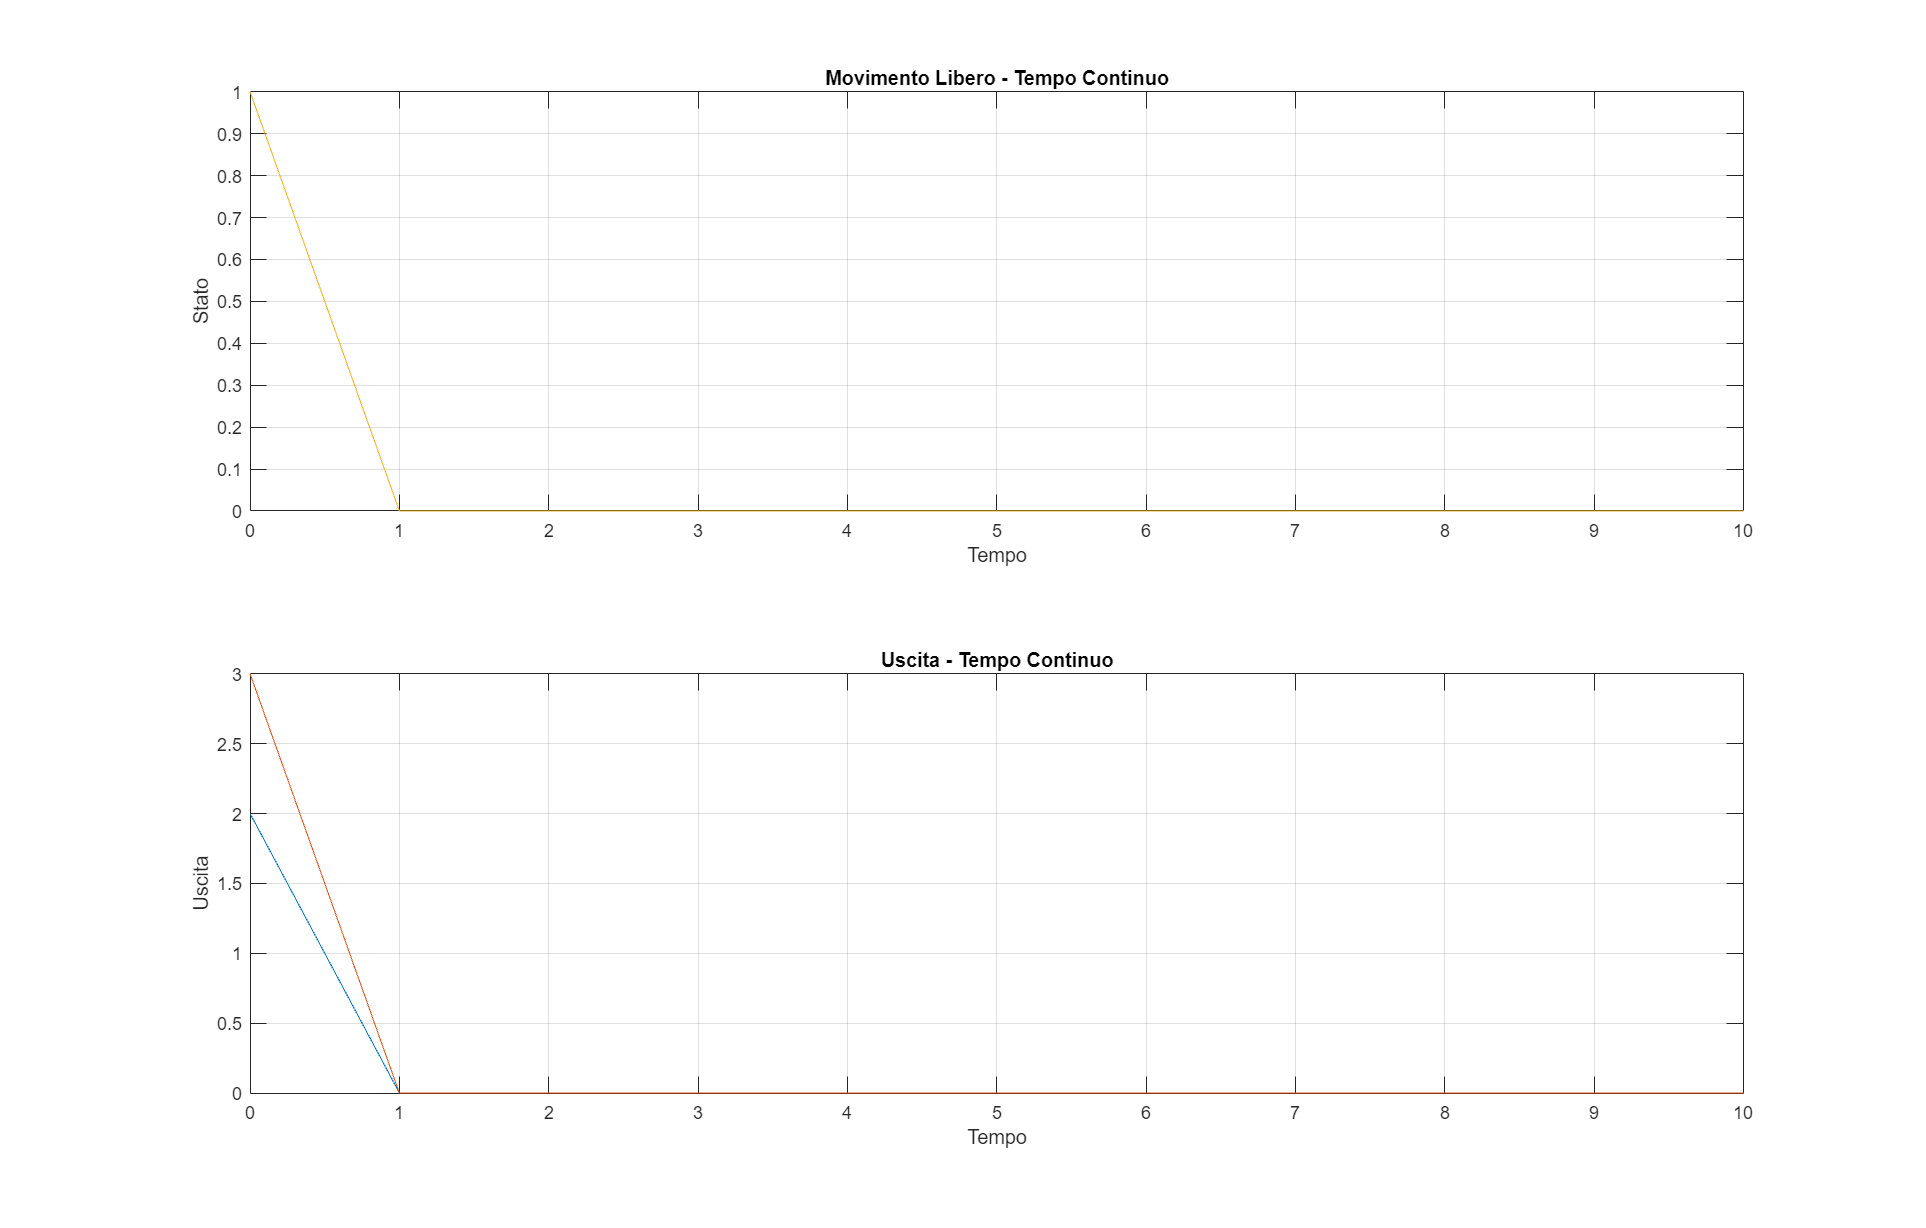

n = 0:1:10;  % Definisci un vettore di tempo da 0 a 10 secondi con 10 campioni

% Simulazione a tempo continuo
[Y, ~, X] = initial(sysC,X0,n); 
figure('Units','normalized', 'Position',[ 0.1, 0.1, 0.75, 0.85]);
% Plot del movimento libero a tempo continuo
subplot(2,1,1)
plot(n, X);
xlabel('Tempo');
ylabel('Stato');
title('Movimento Libero - Tempo Continuo');
grid on; hold on


% Plot dell'uscita
subplot(2, 1, 2);
plot(n, Y);
xlabel('Tempo');
ylabel('Uscita');
title('Uscita - Tempo Continuo');
grid on;

 movimento forzato

XOF=[0;0;0]

XOF =      0
     0
     0


%uC=[heaviside(n) ;heaviside(n)];
Tstop = 10;
Tsampling = 1;
SinPeriod = 2.5;
[uC(:,1), timeSET_D2] = gensig('sine', SinPeriod, Tstop, Tsampling); %generazione seno
[uC(:,2), timeSET_D2] = gensig('sine', SinPeriod, 10,Tsampling);

%[Yf, ~, Xf]=lsim(sysC, uC, n, XOF);
[Yf, ~, Xf]=lsim(sysC, uC, timeSET_D2, XOF);


figure('Units','normalized', 'Position',[ 0.1, 0.1, 0.75, 0.85]);
% Plot del movimento libero a tempo continuo
subplot(2,1,1)
plot(n, Xf);
xlabel('Tempo');
ylabel('Stato');
title('Movimento Libero - Tempo Continuo');
grid on; hold on


% Plot dell'uscita
subplot(2, 1, 2);
plot(n, Yf);
xlabel('Tempo');
ylabel('Uscita');
title('Uscita - Tempo Continuo');
grid on;

movimento di stato totale

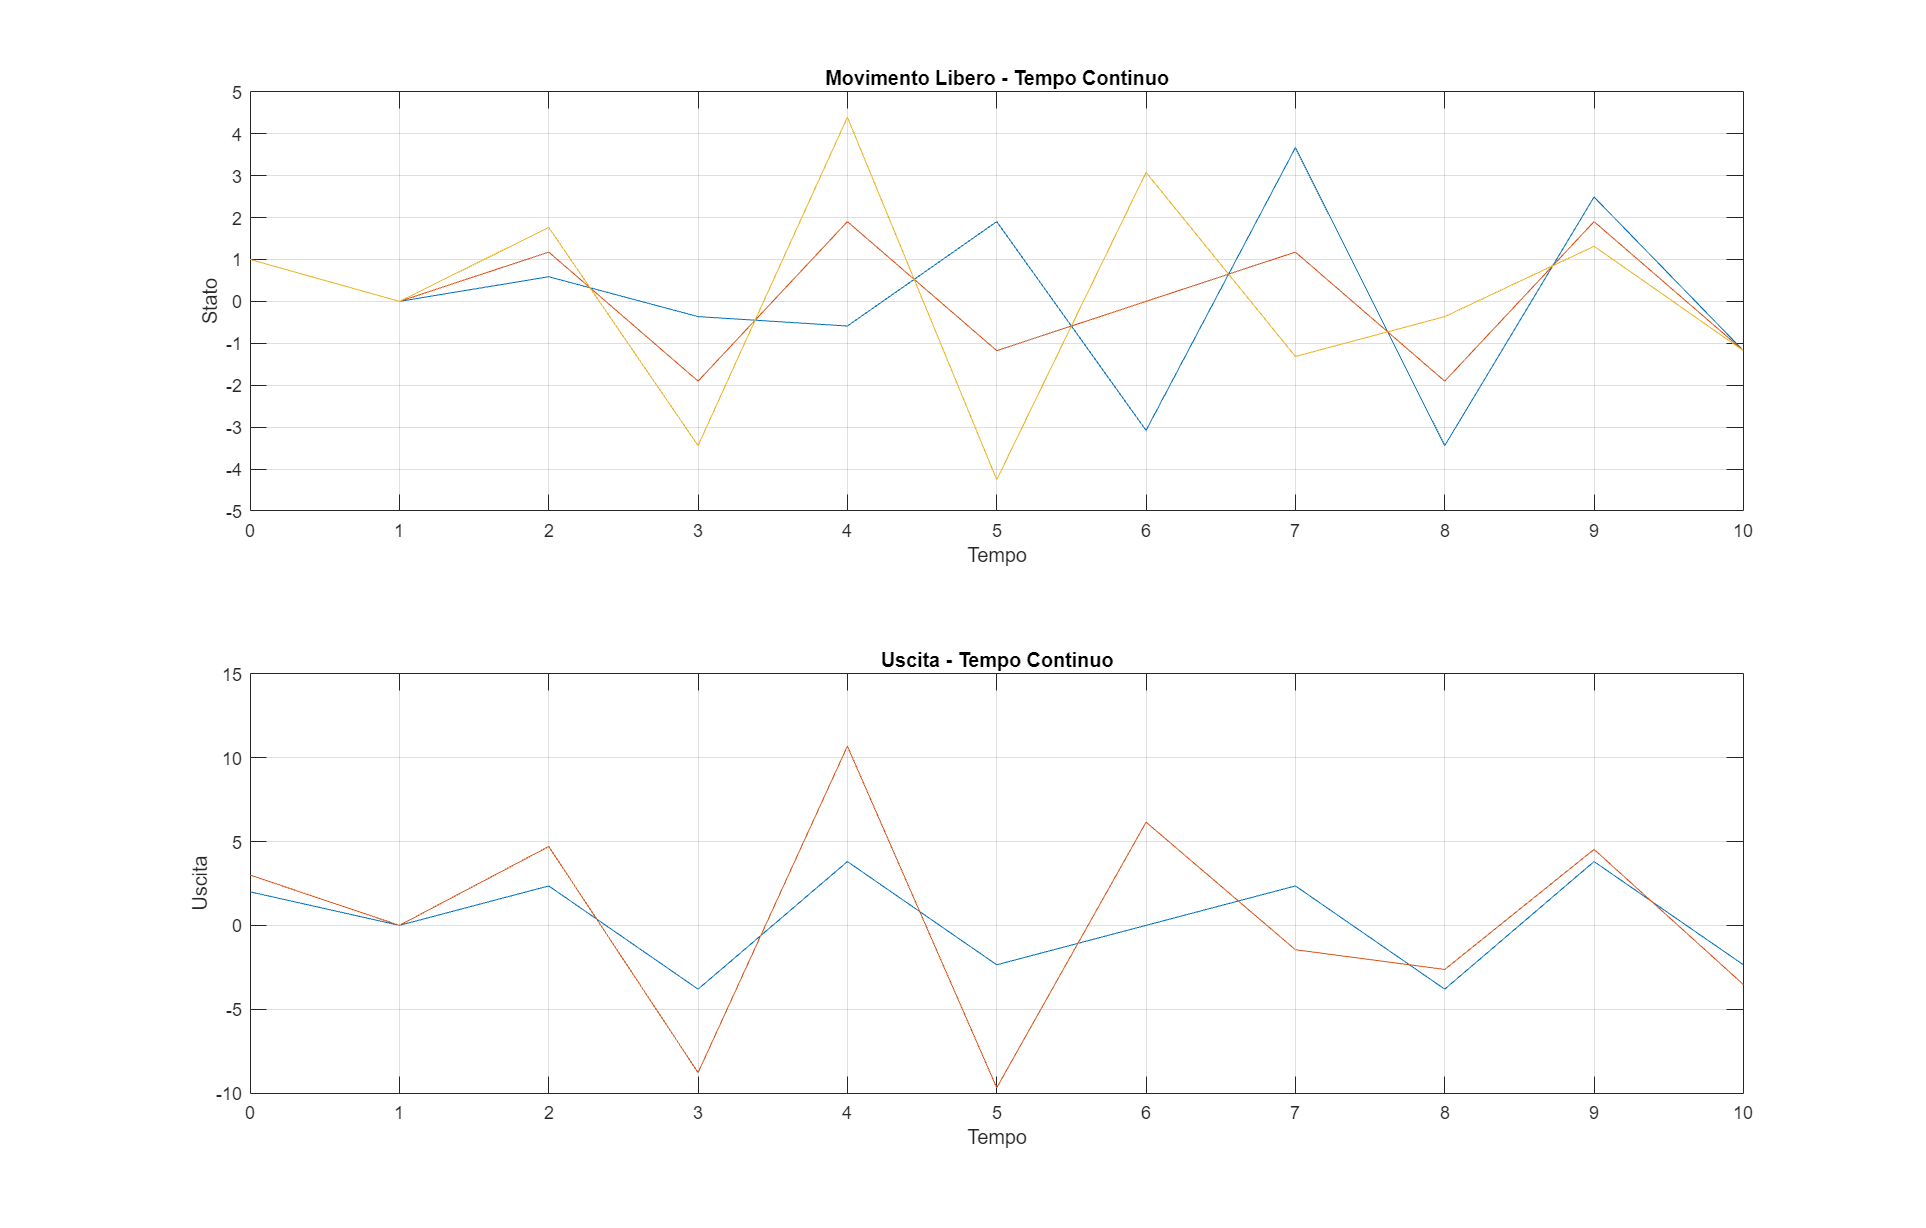

[Yf, ~, Xf]=lsim(sysC, uC, n, X0);

figure('Units','normalized', 'Position',[ 0.1, 0.1, 0.75, 0.85]);
% Plot del movimento libero a tempo continuo
subplot(2,1,1)
plot(n, Xf);
xlabel('Tempo');
ylabel('Stato');
title('Movimento Libero - Tempo Continuo');
grid on; hold on


% Plot dell'uscita
subplot(2, 1, 2);
plot(n, Yf);
xlabel('Tempo');
ylabel('Uscita');
title('Uscita - Tempo Continuo');
grid on;

[Yk, ~, Xk] = lsim(sysC, uC, n, X0);

figure('Units','normalized', 'Position',[ 0.1, 0.1, 0.75, 0.85]);
% Plot del movimento libero a tempo continuo
subplot(2,1,1)
plot(n, Xk);
xlabel('Tempo');
ylabel('Stato');
title('Movimento Libero - Tempo Continuo');
grid on; hold on


% Plot dell'uscita
subplot(2, 1, 2);
plot(n, Yk);
xlabel('Tempo');
ylabel('Uscita');
title('Uscita - Tempo Continuo');
grid on;